clear 
clc
close all

### Definition der Variablen

a = 0.0158;
b = 0.084;
e = 0.0127;
d = 11.5;

### Aufstellen der Strecke als ${\textrm{PDT}}_1$Glied

Tt = 0.2;
Kp = b*d/a;
T1 = 1/a;

s = tf('s');
Fs = b/(s+a)*exp(-Tt*s);

### Aufstellen der Übertragungsfunktionen für den Regler nach dem Ziegler-Nichols Verfahren

Fr = 0.9*T1/(Kp*Tt)+1/(3.33*Tt*s);

### Aufstellen des offenen und geschlossen Regelkreises

L = Fr*Fs;
T = Fr*Fs/(1+Fr*Fs);
S = 1/(1+Fr*Fs);

### Bode Diagramm des offenen Regelkreises

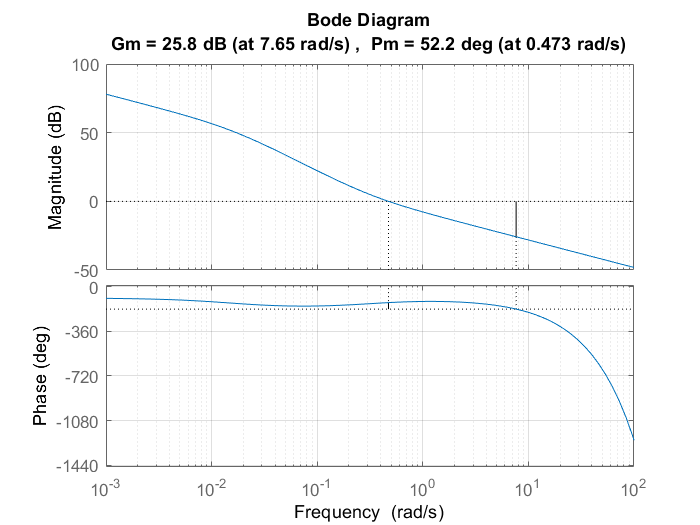

margin(L)
grid on

Tteq = 52.2/(0.473*180/3.14)

Tteq = 1.9252

### Durchführen der Simulation

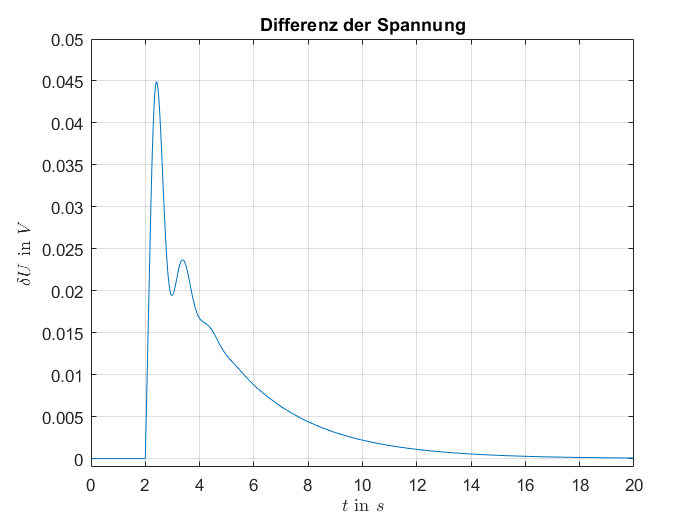

sim("windrad")
figure()
plot(U)
grid on
title("Differenz der Spannung")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$\delta U$ in $V$",'Interpreter','latex')
ylim([-.001 0.05])

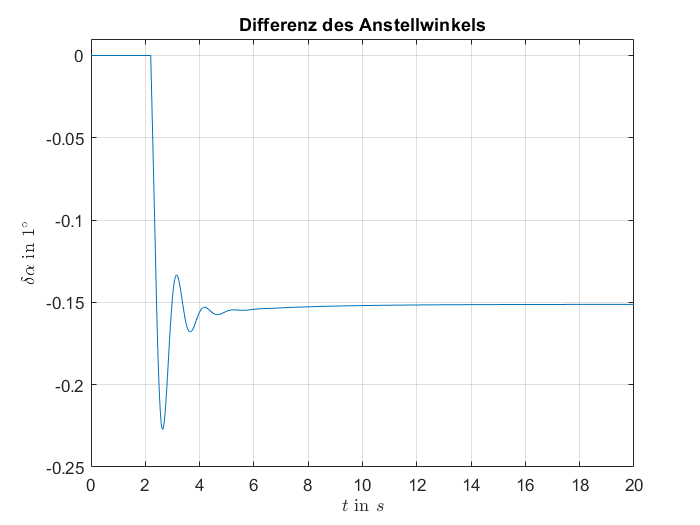


figure()
plot(alpha)
title("Differenz des Anstellwinkels")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$\delta  \alpha$  in  $1^{\circ}$",'Interpreter','latex')
grid on
ylim([-0.25 0.01])


% Ausgabe des Simulink Modells als SVG für die Verwendung in der
% Dokumentation
handle=get_param('windrad','handle');
print(handle,'-dsvg','sim_windrad');
